## Adaptando o algoritmo ao projeto da ponte

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL
format short e

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9;    % Módulo de elasticidade longitudinal [Pa]
A = 0.02 * 0.003;   % Área da seção transversal [m^2]
L = 4 * 10^(-2);   % Metade do comprimento de um elemento
h = 9.5 * 10^(-2); % altura

num_elementos = 25;
num_nos = 15;

x_y = [ 0,   0; % Nó 1
        L,   h; % Nó 2 
        3*L, h; % Nó 3
        5*L, h% Nó 4
        7*L, h; % Nó 5
        9*L, h; % Nó 6
        11*L, h; % Nó 7
        12*L,   0; % Nó 8
        11*L,   0; % Nó 9
        10*L,   0; % Nó 10
        8*L,   0; % Nó 11
        6*L,   0; % Nó 12
        4*L,   0; % Nó 13
        2*L,   0; % Nó 14
        L,     0; % Nó 15
];

% Matriz de incidências de cada elemento
incidencias = [
    1, 2; % Elemento 1
    2, 3; % Elemento 2
    3, 4; % Elemento 3
    4, 5; % Elemento 4
    5, 6; % Elemento 5
    6, 7; % Elemento 6
    7, 8; % Elemento 7
    8, 9; % Elemento 8
    9, 10; % Elemento 9
    10, 11; % Elemento 10
    11, 12; % Elemento 11
    12, 13; % Elemento 12
    13, 14; % Elemento 13
    14, 15; % Elemento 14

    15, 1; % Elemento 15
    2, 14; % Elemento 16
    14, 3; % Elemento 17
    3, 13; % Elemento 18
    13, 4; % Elemento 19
    4, 12; % Elemento 20
    12, 5; % Elemento 21
    5, 11; % Elemento 22
    11, 6; % Elemento 23
    6, 10; % Elemento 24
    10, 7; % Elemento 25
];

% ============================================================================

% Inicializar matriz de rigidez global
num_nos = size(x_y, 1);
num_elementos = size(incidencias, 1);
Kg = zeros(2 * num_nos);

% Montar a matriz de rigidez global
for i = 1:num_elementos
    % Nós do elemento
    n1 = incidencias(i, 1);
    n2 = incidencias(i, 2);
    
    % Coordenadas dos nós
    x1 = x_y(n1, 1);
    y1 = x_y(n1, 2);	
    x2 = x_y(n2, 1);
    y2 = x_y(n2, 2);

    % Comprimento do elemento
    L = sqrt((x2 - x1)^2 + (y2 - y1)^2);
    
    % Cálculo dos senos e cossenos
    c = (x2 - x1) / L;
    s = (y2 - y1) / L;
    
    % Matriz de rigidez do elemento
    k = (E * A / L) * [c^2, c*s, -c^2, -c*s;
                       c*s, s^2, -c*s, -s^2;
                      -c^2, -c*s, c^2, c*s;
                      -c*s, -s^2, c*s, s^2];
    
    % Índices globais de graus de liberdade para o elemento
    dof = [2*n1-1, 2*n1, 2*n2-1, 2*n2];
    
    % Adiciona a matriz de rigidez do elemento à matriz de rigidez global
    Kg(dof, dof) = Kg(dof, dof) + k;
end

ans =    4.0000e-02


ans =    9.5000e-02


ans =    8.0000e-02


ans =      0


ans =    8.0000e-02


ans =      0


ans =    8.0000e-02


ans =      0


ans =    8.0000e-02


ans =      0


ans =    8.0000e-02


ans =      0


ans =    4.0000e-02


ans =   -9.5000e-02


ans =   -4.0000e-02


ans =      0


ans =   -4.0000e-02


ans =      0


ans =   -8.0000e-02


ans =      0


ans =   -8.0000e-02


ans =      0


ans =   -8.0000e-02


ans =      0


ans =   -8.0000e-02


ans =      0


ans =   -4.0000e-02


ans =      0


ans =   -4.0000e-02


ans =      0


ans =    4.0000e-02


ans =   -9.5000e-02


ans =    4.0000e-02


ans =    9.5000e-02


ans =    4.0000e-02


ans =   -9.5000e-02


ans =    4.0000e-02


ans =    9.5000e-02


ans =    4.0000e-02


ans =   -9.5000e-02


ans =    4.0000e-02


ans =    9.5000e-02


ans =    4.0000e-02


ans =   -9.5000e-02


ans =    4.0000e-02


ans =    9.5000e-02


ans =    4.0000e-02


ans =   -9.5000e-02


ans =    4.0000e-02


ans =    9.5000e-02


disp("Matriz de rigidez geral:");

Matriz de rigidez geral:


disp(Kg);

   3.3341e+08   4.3718e+07  -1.8408e+07  -4.3718e+07            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0  -3.1500e+08            0
   4.3718e+07   1.0383e+08  -4.3718e+07  -1.0383e+08            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
  -1.8408e+07  -4.3718e+07   1.9432e+08            0  -1.5750e+08            0            0            0            0            0            0            0            0            0            0            0          

% PASSO 4: Montar o vetor global de forças. No grau de liberdade com restrição deve aparecer um esforço de reação.
Pg = zeros(num_nos*2, 1);

% Vou adicionar manualmente, pq n tem como automatizar isso
Pg(4*2) = -300;      % R4y
Pg(5*2) = -300;      % R5y

disp("Vetor global de forças:");

Vetor global de forças:


disp(Pg);

     0
     0
     0
     0
     0
     0
     0
  -300
     0
  -300
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Condições de contorno (graus de liberdade restritos)
gdls_restritos = [17, 18, 29, 30];
gdls_livres = [];
for i = 1:30
    if ~ismember(i, gdls_restritos)
        gdls_livres(end+1) = i;
    end
end

% Reduzir a matriz de rigidez e o vetor de forças para o sistema reduzido
K_reduzida = Kg(gdls_livres, gdls_livres);
P_reduzida = Pg(gdls_livres);

% Resolver o sistema para obter os deslocamentos nos GDLs livres (u2, u5, u6)
d_reduzida = svd(K_reduzida) \ P_reduzida;

% Reconstruir o vetor de deslocamentos completo
d_completa = zeros(2 * num_nos, 1);
d_completa(gdls_livres) = d_reduzida;

% Calcular as reações de apoio
R = Kg * d_completa - Pg;

disp('Vetor de Forças Globais [F_global]:');

Vetor de Forças Globais [F_global]:


disp(Pg);

     0
     0
     0
     0
     0
     0
     0
  -300
     0
  -300
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



disp('Deslocamentos:');

Deslocamentos:


disp(d_completa);

  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
            0
            0
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
  -7.6687e-08
            0
            0



disp('Reações de Apoio:');

Reações de Apoio:


disp(R(gdls_restritos));

   4.8313e+01
            0
   4.8313e+01
            0



disp('Deslocamentos nos graus de liberdade livres:');

Deslocamentos nos graus de liberdade livres:


for i = 1:length(gdls_livres)
    gdl = gdls_livres(i);
    deslocamento = d_completa(gdl);
    fprintf('u%d = %.2e m\n', gdl, deslocamento);
end

u1 = -7.67e-08 m
u2 = -7.67e-08 m
u3 = -7.67e-08 m
u4 = -7.67e-08 m
u5 = -7.67e-08 m
u6 = -7.67e-08 m
u7 = -7.67e-08 m
u8 = -7.67e-08 m
u9 = -7.67e-08 m
u10 = -7.67e-08 m
u11 = -7.67e-08 m
u12 = -7.67e-08 m
u13 = -7.67e-08 m
u14 = -7.67e-08 m
u15 = -7.67e-08 m
u16 = -7.67e-08 m
u19 = -7.67e-08 m
u20 = -7.67e-08 m
u21 = -7.67e-08 m
u22 = -7.67e-08 m
u23 = -7.67e-08 m
u24 = -7.67e-08 m
u25 = -7.67e-08 m
u26 = -7.67e-08 m
u27 = -7.67e-08 m
u28 = -7.67e-08 m


deformacoes = zeros(num_elementos, 1);
tensoes = zeros(num_elementos, 1);

% Calcular deformação e tensão para cada elemento
for i = 1:num_elementos
    n1 = incidencias(i, 1);
    n2 = incidencias(i, 2);
    
    % Coordenadas dos nós
    x1 = x_y(n1, 1);
    y1 = x_y(n1, 2);
    x2 = x_y(n2, 1);
    y2 = x_y(n2, 2);
    
    % Comprimento do elemento
    L = sqrt((x2 - x1)^2 + (y2 - y1)^2);
    
    % Deslocamentos dos nós do elemento
    u_n1_x = d_completa(2*n1 - 1);
    u_n1_y = d_completa(2*n1);
    u_n2_x = d_completa(2*n2 - 1);
    u_n2_y = d_completa(2*n2);
    
    deformacao = ((u_n2_x - u_n1_x) * (x2 - x1) + (u_n2_y - u_n1_y) * (y2 - y1)) / L^2;
    deformacoes(i) = deformacao;
    
    tensao = E * deformacao;
    tensoes(i) = tensao;
end

disp('Deformações em cada elemento:');

Deformações em cada elemento:


disp(deformacoes);

            0
            0
            0
            0
            0
            0
            0
  -1.9172e-06
   1.9172e-06
            0
            0
            0
            0
  -1.9172e-06
   1.9172e-06
            0
            0
            0
            0
            0
            0
            0
            0
            0
            0



disp('Tensões em cada elemento (Pa):');

Tensões em cada elemento (Pa):


disp(tensoes);

            0
            0
            0
            0
            0
            0
            0
  -4.0261e+05
   4.0261e+05
            0
            0
            0
            0
  -4.0261e+05
   4.0261e+05
            0
            0
            0
            0
            0
            0
            0
            0
            0
            0



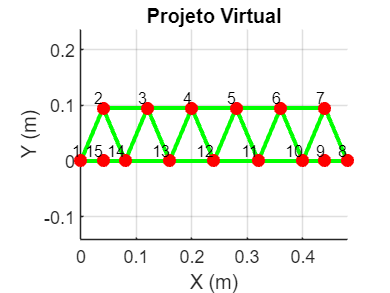

% Projeto Virtual
figure;
hold on;
axis equal;
grid on;
title('Projeto Virtual');
xlabel('X (m)');
ylabel('Y (m)');

for i = 1:num_elementos
    n1 = incidencias(i, 1);
    n2 = incidencias(i, 2);
   
    x_coords = [x_y(n1, 1), x_y(n2, 1)];
    y_coords = [x_y(n1, 2), x_y(n2, 2)];
    
    plot(x_coords, y_coords, 'g-', 'LineWidth', 2);
end

% Desenhar os nós
for i = 1:num_nos
    plot(x_y(i, 1), x_y(i, 2), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
    text(x_y(i, 1), x_y(i, 2), sprintf(' %d', i), 'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

hold off;